# PROCESAMIENTO DE DATOS GRUPO 2

clear all;clc;close all;
opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
load("tab3ML.mat");
[UniqueData,Repeatedpoints]=repeated_data(tab3ML);%cambiar nombre de la función

nRepeatedPoints = 0

Uniquedata = 162×24 table
    Infomean1    Infomean2    Infomean3    Infomean4    Infomean5    Infomean6    Infomean7     Infomean8    Infomean9    Infomean10    Infomean11    Infomean12    Infomean13    Infomean14    Infomean15    Infomean16    Infomean17    Infomean18    Infomean19    Infomean20    Infomean21    Infomean22    Infomean23    Var24
    _________    _________    _________    _________    _________    _________    __________    _________ 

Nombres = opts.VariableNames;
Nombres;
PreprocessedDdata = processed(UniqueData)

PreprocessedDdata = 162×24 table
     Área     Longitud eje mayor    Longitud eje menor    Área convexa    Circularidad    Perímetro    Distancia mínima entre núcleos    Varianza área    Varianza área convexa    Varianza circularidad    Varianza perímetro    Varianza longitud eje mayor    Ratio medio distancia ejes    Porcentaje de núcleos    Varianza de la distancia del eje menor    Compactabilidad de núcleos    Distancia media entre núcleos    Varianza distancia entre núcleos    Varianza del ratio de distancia ejes    Contraste    Correlación    Homogenidad    Energía     Tipo de cáncer

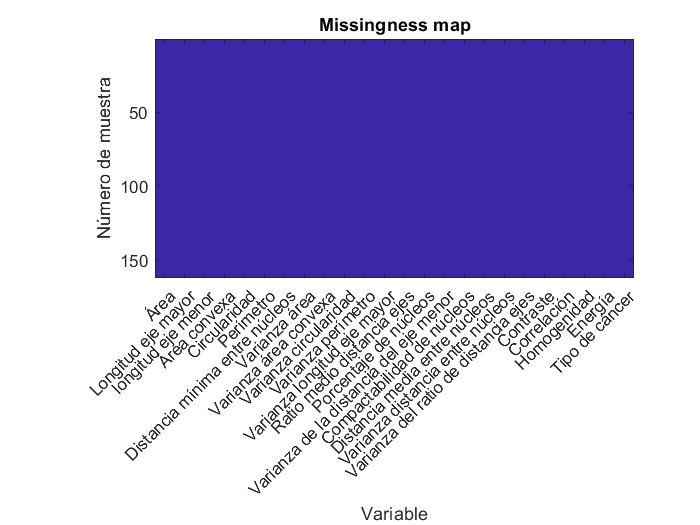

imagesc(ismissing(PreprocessedDdata,{'' '.' 'NA' NaN -99}))
xticks(1:length(Nombres));
xticklabels(Nombres);
xtickangle(45)
title('Missingness map');
xlabel('Variable');
ylabel('Número de muestra')

a=[1:7,13,14,16,17,20:23];
b=[24];
c=b;
units= ["um^2","um","um","um^2","-","um","um","-v","-v","-v","-v","-v","-","%(unitaria)","-v","-","um","-v","-v","-","-","-","-"];
[dataN,response_var,independent_vars,categorical_vars] =inconsistent_data(PreprocessedDdata,a,b,c);

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars(:,i));
    maximo(i) = max(h(2).XData);
    minimo(i) = min(h(2).XData);
    if minimo(i)<0
        minimo(i) = 0;
    end
    histfit(independent_vars(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end
l=1;

for p=1:height(dataN)
    if independent_vars(p,1:width(independent_vars))>minimo(1:width(independent_vars)) & independent_vars(p,1:width(independent_vars))<maximo(1:width(independent_vars))
        dataN1(l,:)=(dataN(p,:));
        l= l+1;
    end
end
independent_vars1 =  table2array(dataN1(:,a));
% independent_vars1 = table2array(independent_vars1);
for i=1:15
    fprintf('Mean value for variable %s is %.2f\n', Nombres{a(i)},mean(independent_vars1(:,i)));%FALTA TRADUCIR
    fprintf('Median for variable %s is %.2f\n', Nombres{a(i)},median(independent_vars1(:,i)));
    fprintf('Mode for variable %s is %.2f\n', Nombres{a(i)},mode(round(independent_vars1(:,i),1)));
    fprintf('Max. value for variable %s is %.2f\n', Nombres{a(i)},max(independent_vars1(:,i)));
    fprintf('Min. value for variable %s is %.2f\n', Nombres{a(i)},min(independent_vars1(:,i)));
    fprintf('Standard deviation for variable %s is %.2f\n \n', Nombres{a(i)},std(independent_vars1(:,i)));
end

Mean value for variable Área is 11.74


Median for variable Área is 11.48


Mode for variable Área is 9.70


Max. value for variable Área is 20.07


Min. value for variable Área is 5.05


Standard deviation for variable Área is 2.81
 


Mean value for variable Longitud eje mayor is 5.42


Median for variable Longitud eje mayor is 5.44


Mode for variable Longitud eje mayor is 5.40


Max. value for variable Longitud eje mayor is 6.53


Min. value for variable Longitud eje mayor is 3.66


Standard deviation for variable Longitud eje mayor is 0.50
 


Mean value for variable longitud eje menor is 2.75


Median for variable longitud eje menor is 2.75


Mode for variable longitud eje menor is 2.70


Max. value for variable longitud eje menor is 3.38


Min. value for variable longitud eje menor is 1.96


Standard deviation for variable longitud eje menor is 0.27
 


Mean value for variable Área convexa is 15.48


Median for variable Área convexa is 14.93


Mode for variable Área convexa is 14.20


Max. value for variable Área convexa is 29.76


Min. value for variable Área convexa is 6.06


Standard deviation for variable Área convexa is 4.12
 


Mean value for variable Circularidad is 0.60


Median for variable Circularidad is 0.59


Mode for variable Circularidad is 0.60


Max. value for variable Circularidad is 0.78


Min. value for variable Circularidad is 0.51


Standard deviation for variable Circularidad is 0.04
 


Mean value for variable Perímetro is 16.59


Median for variable Perímetro is 16.54


Mode for variable Perímetro is 16.10


Max. value for variable Perímetro is 22.69


Min. value for variable Perímetro is 9.73


Standard deviation for variable Perímetro is 2.40
 


Mean value for variable Distancia mínima entre núcleos is 0.00


Median for variable Distancia mínima entre núcleos is 0.00


Mode for variable Distancia mínima entre núcleos is 0.00


Max. value for variable Distancia mínima entre núcleos is 0.00


Min. value for variable Distancia mínima entre núcleos is 0.00


Standard deviation for variable Distancia mínima entre núcleos is 0.00
 


Mean value for variable Ratio medio distancia ejes is 2.13


Median for variable Ratio medio distancia ejes is 2.09


Mode for variable Ratio medio distancia ejes is 2.00


Max. value for variable Ratio medio distancia ejes is 2.61


Min. value for variable Ratio medio distancia ejes is 1.89


Standard deviation for variable Ratio medio distancia ejes is 0.15
 


Mean value for variable Porcentaje de núcleos is 0.97


Median for variable Porcentaje de núcleos is 0.93


Mode for variable Porcentaje de núcleos is 0.90


Max. value for variable Porcentaje de núcleos is 1.67


Min. value for variable Porcentaje de núcleos is 0.23


Standard deviation for variable Porcentaje de núcleos is 0.23
 


Mean value for variable Compactabilidad de núcleos is 0.44


Median for variable Compactabilidad de núcleos is 0.45


Mode for variable Compactabilidad de núcleos is 0.40


Max. value for variable Compactabilidad de núcleos is 0.74


Min. value for variable Compactabilidad de núcleos is 0.14


Standard deviation for variable Compactabilidad de núcleos is 0.09
 


Mean value for variable Distancia media entre núcleos is 0.27


Median for variable Distancia media entre núcleos is 0.26


Mode for variable Distancia media entre núcleos is 0.30


Max. value for variable Distancia media entre núcleos is 0.57


Min. value for variable Distancia media entre núcleos is 0.08


Standard deviation for variable Distancia media entre núcleos is 0.09
 


Mean value for variable Contraste is 0.28


Median for variable Contraste is 0.26


Mode for variable Contraste is 0.30


Max. value for variable Contraste is 0.81


Min. value for variable Contraste is 0.14


Standard deviation for variable Contraste is 0.12
 


Mean value for variable Correlación is 0.95


Median for variable Correlación is 0.95


Mode for variable Correlación is 1.00


Max. value for variable Correlación is 0.99


Min. value for variable Correlación is 0.88


Standard deviation for variable Correlación is 0.02
 


Mean value for variable Homogenidad is 0.88


Median for variable Homogenidad is 0.88


Mode for variable Homogenidad is 0.90


Max. value for variable Homogenidad is 0.93


Min. value for variable Homogenidad is 0.76


Standard deviation for variable Homogenidad is 0.03
 


Mean value for variable Energía is 0.12


Median for variable Energía is 0.11


Mode for variable Energía is 0.10


Max. value for variable Energía is 0.21


Min. value for variable Energía is 0.06


Standard deviation for variable Energía is 0.03
 


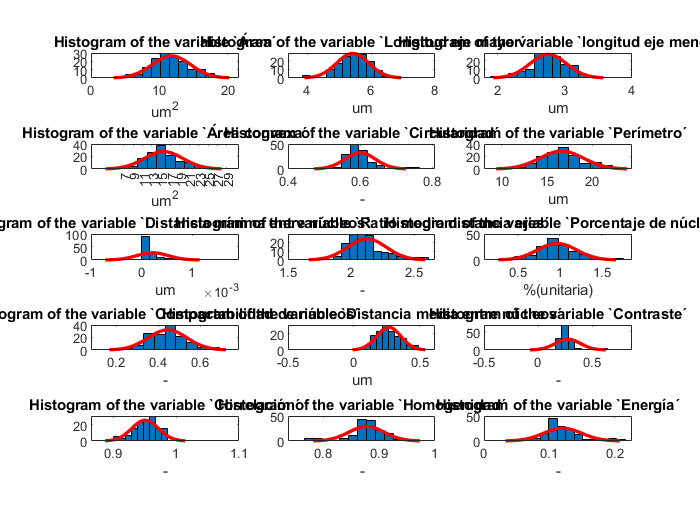

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars1(:,i));
    histfit(independent_vars1(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

figure ()
%corrplot(dataN1(:,1:23));


f=24;
[m1,n1]=size(dataN1);
categorical_vars1=table2array(dataN1(:,f));
dataN3=[];
dataN4=[];
for i = 1:m1
%     A=categorical_vars(:,f);
%     B=removecats(A);
%     C=categories(B);
%     n=length(C);
%       categorical
%     if n==2
        if categorical_vars1 (i) == "FEA"
            dataN3 = [dataN3 i];
        end
        if categorical_vars1 (i) == "ADH"
            dataN4 = [dataN4 i];
        end
end


    
for j=1:23
    optA=transpose(table2array(dataN1(dataN3,j)));
    optB=transpose(table2array(dataN1(dataN4,j)));
    [H1(j),p1(j)] = ttest2(optA,optB);
end


% fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT),Xt,yt);
% tokeep = sequentialfs(fun,dataN1{:, 2:end},dataN1{:, 1})
dataN2=(dataN1);
%dataN2=table2array(dataN2);
for i=1:23
    dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
end
% dataN2=dataN1;
idx = fscmrmr(dataN2,"Tipo de cáncer")

idx =     21    14    18    13    16     5     7    10    23     3     9    19    17     2    20    12    15    22     8     1     6    11     4


A=[6, 7, 8, 10, 11, 14, 19, 20, 21, 23,24]

A =      6     7     8    10    11    14    19    20    21    23    24


dataN2=dataN2(:,A);

# ALGORITMOS

k=8;
cvpt = cvpartition(dataN2.("Tipo de cáncer"),"Holdout",0.30);
dataTrain =dataN2(training(cvpt),:);
dataTest = dataN2(test(cvpt),:);
cvpt = cvpartition(dataTrain.("Tipo de cáncer"),"KFold",k)

cvpt = K-fold cross validation partition
   NumObservations: 101
       NumTestSets: 8
         TrainSize: 89  88  88  88  88  88  89  89
          TestSize: 12  13  13  13  13  13  12  12

## 1.KNN

mdlKNN = fitcknn(dataTrain, "Tipo de cáncer","NumNeighbors",3,"CVPartition",cvpt);
mdlLossKNN = kfoldLoss(mdlKNN) %This row will print the mean Loss value. 

mdlLossKNN = 0.3366

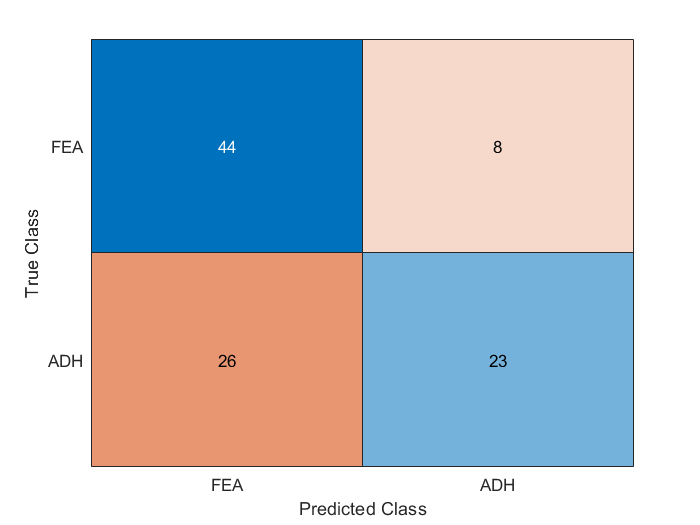

mdlLossKNN = kfoldLoss(mdlKNN, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdlKNN);
figure()
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 2. DECISION TREE

mdlTree = fitctree(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlTreeLoss = kfoldLoss(mdlTree)

mdlTreeLoss = 0.1881

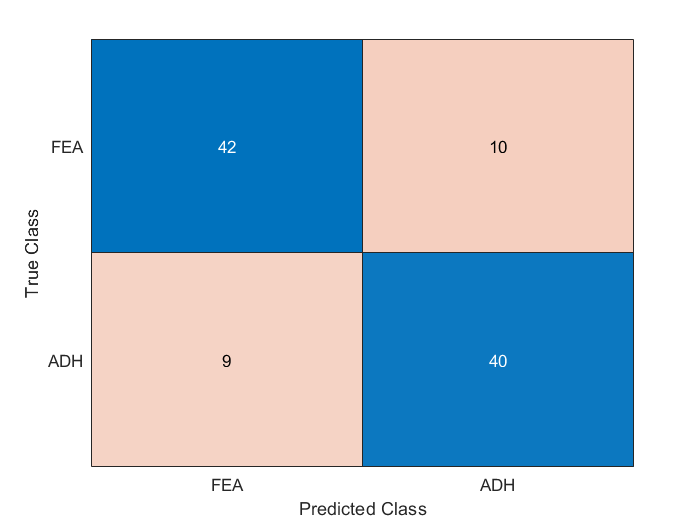

% mdlTreeLoss = 0.0927
mdlTreeLoss = kfoldLoss(mdlTree, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlTree);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 3. **Naive Bayes**

mdlNB = fitcnb(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlNBLoss = kfoldLoss(mdlNB)

mdlNBLoss = 0.3267

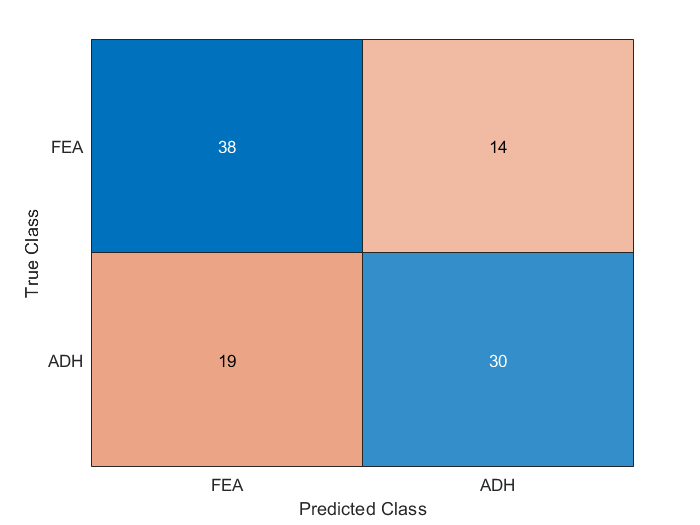

% mdlNBLoss = 0.0677
mdlNBLoss = kfoldLoss(mdlNB, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlNB);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## **4.- LINEAR Discriminant Analysis**

mdlDisAn = fitcdiscr(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlDisAnLoss = kfoldLoss(mdlDisAn)

mdlDisAnLoss = 0.2970

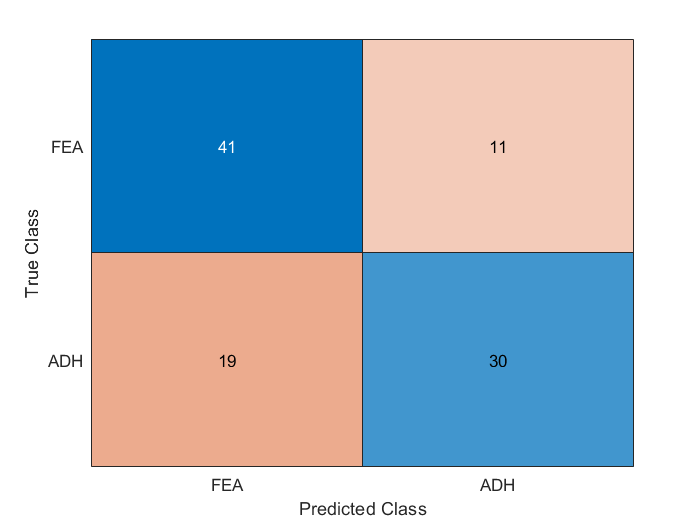


mdlDisAnLoss = kfoldLoss(mdlDisAn, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 5-QUADRATIC Discriminant Analysis

mdlDisAnQ = fitcdiscr(dataTrain, "Tipo de cáncer","DiscrimType","quadratic","CVPartition",cvpt);
mdlDisAnQLoss = kfoldLoss(mdlDisAnQ)

mdlDisAnQLoss = 0.2574

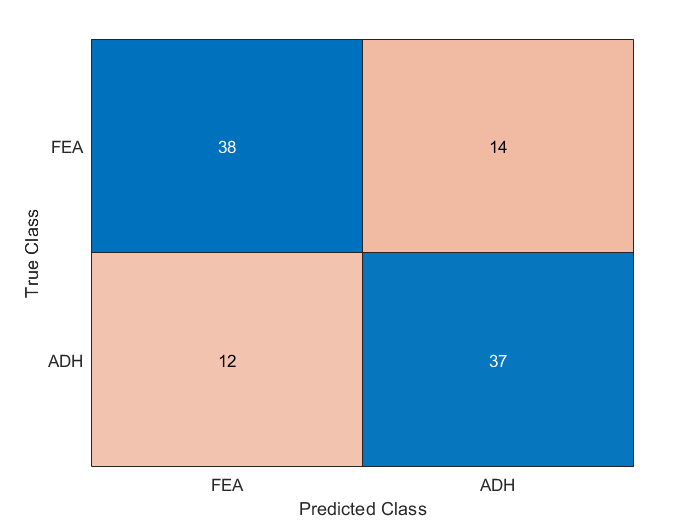

mdlDisAnQLoss = kfoldLoss(mdlDisAnQ, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAnQ);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 6-SVM

mdlSvm = fitcsvm(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlSvmLoss = kfoldLoss(mdlSvm)

mdlSvmLoss = 0.2970

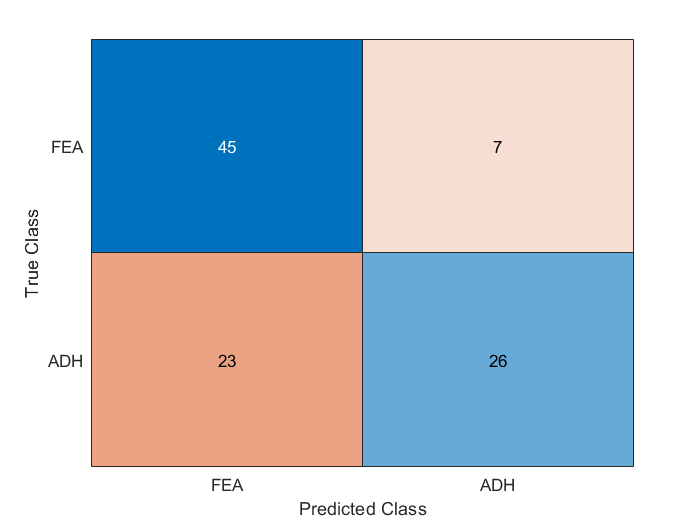


mdlSvmLoss = kfoldLoss(mdlSvm, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlSvm);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## Línea de decisión

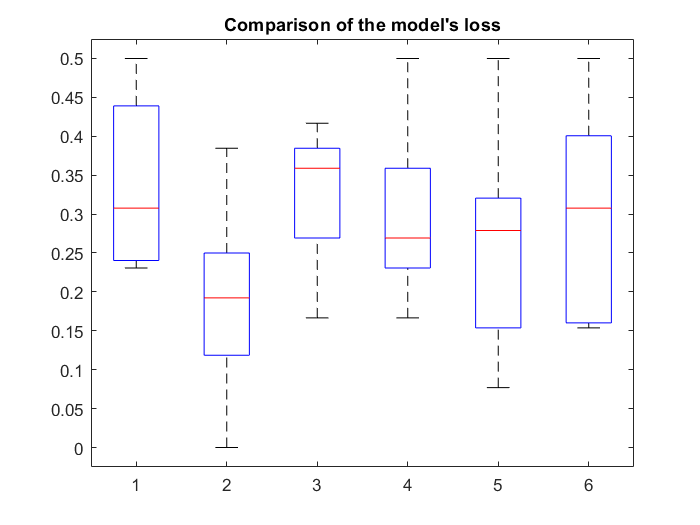

loss_matrix = [(mdlLossKNN),(mdlTreeLoss),(mdlNBLoss),(mdlDisAnLoss),(mdlDisAnQLoss),(mdlSvmLoss)];
boxplot(loss_matrix)
title("Comparison of the model's loss")


opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
Av = struct2cell(load("3_FEA.mat"));
Av = Av{1,1};
Bv = struct2cell(load("4_ADH.mat"));
Bv = Bv{1,1};
Taula = [Av; Bv];
% for i=1:23
%     dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
% end
% data_todo = dataN2;
Taulav=Taula;
for i=1:23
    Taulav(:,i)=array2table(rescale(table2array(Taula(:,i))));
end

TaulaV = processed(Taulav);
TaulaV(:, [1,2,3,4,5,9,12,13,15,16,17,18,22]) = [];

final_mdl = fitcecoc(dataN2 , "Tipo de cáncer",'Coding','onevsone','Learners','discriminant');
lrnrs = {templateKNN("NumNeighbors",4), templateDiscriminant, templateKNN("NumNeighbors", 2)}

lrnrs = 1×3 cell array
    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}


%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrnrs)

predictions = predict(final_mdl,TaulaV);
mdlLoss = loss(final_mdl,TaulaV)

mdlLoss = 0.2933

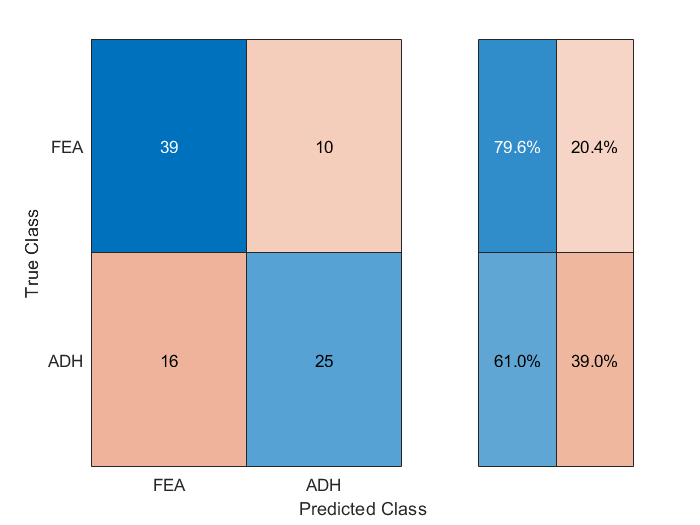

confusionchart(TaulaV.("Tipo de cáncer"),predictions,"RowSummary","row-normalized");

accuracy = sum(TaulaV.("Tipo de cáncer")==predictions)/numel(TaulaV.("Tipo de cáncer"))

accuracy = 0.7111